# 

# IHA-4306 FUNDAMENTAL OF MOBILE ROBOTICS - ASSIGNMENT 1

Group 8: 

Joe Samuel David     267598 

Tuomas Evert Laakso 240047

Zaigham Sultan     267951

**NOTE: **AT THE TIME OF SUBMISSION THE main.m file was tested and all the solutions were found to be working perfectly. However in this file, the Matlab Live Script, solution to part d and the bonus was found not to be working at times. In such case, the main.m file can be run to check its working.

Each stage the pause function is used so it is necessary to press any key to advance to subsequent answers

The Bonus question takes about a minute to execute

## SOLUTION A: GENERATION OF UNDIRECTED AND DIRECTED GRAPH

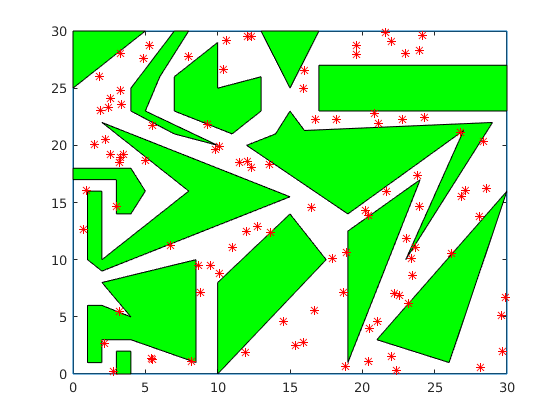

clear all
close all
clc

% rewrite scenario==1 for preproduced data;
% recommended to use scenario for Solution for d as preproduced data clearly
% shows the movement of robot with and without a robot in the scene. This
% clarity may not be present during  random runtime.
scenario=0;

if scenario==1
    load scenario;
else
    % number of nodes 
    ns=100;
    map=map_definition();
    
    % % generate random nodes
    [map, nodelocation]= generate_node(map,ns);
end


% create undirected graph and its edges
[undirectedGraph,unedges]=generate_undirected_graph(map,nodelocation);

Undefined function 'polyxpoly' for input arguments of type 'double'.

Error in generate_undirected_graph (line 18)
        [xi,yi] = polyxpoly(x1,y1,map.obsx,map.obsy);


% create directed maps , its edges Index which shows which new node has the
% same location with original nodes, and biloc refer all new nods location
[bigraph,edges,nodIndex,biloc]=generate_directed_graph(undirectedGraph,nodelocation);

% create directed graph for matlab plotting
G = digraph(bigraph); %,nodename) ;
figure;plot(G,'Layout','force')

## SOLUTION B: PATH PLANNING ALGORITHMS

% define start and end point of simulation
startp=[5, 29, 0];
endp=[29, 20, 0];

% add start and end location as a new 2 nodes in undirected map.
% n+1 th node is start point, n+2th node is end point
[extungraph,exnodelocation,exunedges ]=addstartendpoint2ungraph(map,undirectedGraph,nodelocation,unedges,startp,endp);
exundnodIndex=[1:ns+2];
snodeund=ns+1;
enodeund=ns+2;
% update directed graph according to new added two nodes
[exbigraph,exbiloc,exedges,exnodIndex,startnode,endnode ]=addstartendpoint2bigraph(bigraph,extungraph,biloc,edges,nodIndex,exnodelocation,startp,endp);


% optimal path with dijkstra on directional map
[Route Cost] = dijkstra(exbigraph,exbiloc,startnode);
rt=Route{endnode};
dijkstra_route=exbiloc(rt,:);
cost=pathcost(dijkstra_route);
drawRoute('dijkstra',startnode,endnode,exnodelocation,exnodIndex,exunedges,rt,cost);
pause;

% optimal path with astar on directional map
[Route] = astar2(exbigraph,exbiloc,startnode,endnode);
astar_route=exbiloc(Route,:);
cost=pathcost(astar_route);
drawRoute('Astar',startnode,endnode,exnodelocation,exnodIndex,exunedges,Route,cost);
pause;

% optimal path with dynamic programming on undirectional map
[parent, Route]=dynamicpathplanning(extungraph,exnodelocation,exundnodIndex,snodeund,enodeund);
dpundirected_route=exnodelocation(Route,:);
cost=pathcost(dpundirected_route);
drawRoute('Dynamic Programming on undirected map',snodeund,enodeund,exnodelocation,exundnodIndex,exunedges,Route,cost);
pause;

% optimal path with dynamic programming on directional map
[bparent, bRoute]=dynamicpathplanning(exbigraph,exbiloc,exnodIndex,startnode,endnode);
dpdirected_route=exbiloc(bRoute,:);
cost=pathcost(dpdirected_route);
drawRoute('Dynamic Programming on directed map',startnode,endnode,exnodelocation,exnodIndex,exunedges,bRoute,cost);
pause;

## SOLUTION C: VISULIZATION OF A* ALGORITHM IN GAZEBO

Please run gazebosim.m file with roscore and the launch file

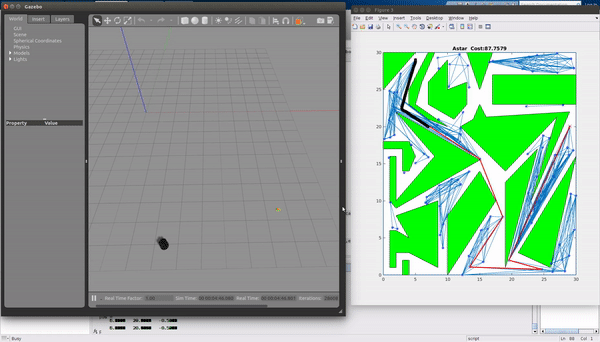

## SOLUTION D: PATH PLANNING WITH TWO ROBOTS MOVING SIMULTANEOUSLY

NOTE: As the black line below is the path followed by the robot using the joint route planning algorithm while the yellow line is the path followed without the algorithm.

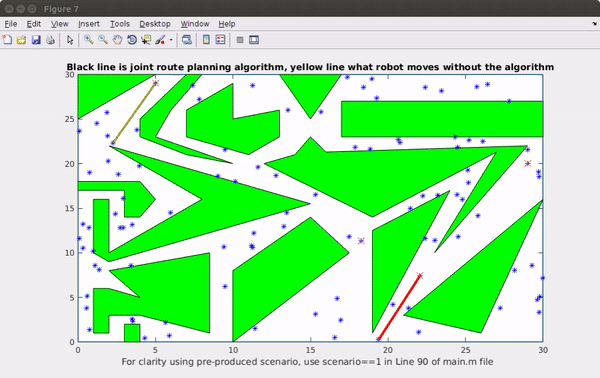

% solving robot routing while there is another robot which locations along
% the time is known.

% define maximum time step size for two robot example
ts=20;

% take start and and point of another robot.
if scenario==0
    map_definition();
    hold on;
    for i=1:size(nodelocation,1)
        plot(nodelocation(:,1),nodelocation(:,2),'b*');
    end
    title('right click for other robot''s start and end points');
    [gx gy]=ginput(2);
    hold off;
end

% find the nearest node for given start and end point for othe robot.
dist=nodelocation-[gx(1) gy(1) 0];
dist=dist(:,1).^2+dist(:,2).^2;
[mn mni]=min(dist);
ostartnode=mni;
dist=nodelocation-[gx(2) gy(2) 0];
dist=dist(:,1).^2+dist(:,2).^2;
[mn mni]=min(dist);
oendnode=mni;

% find optimum path for another robot with djkstra on undirected map
% which we do not care about rotation for memory problem
[Route Cost] = dijkstra(extungraph,exnodelocation,ostartnode);
oroute=Route{oendnode};
% find optimum path for robot if there is not another robot.
[Route Cost] = dijkstra(extungraph,exnodelocation,snodeund);
org_route=Route{enodeund};


% create time-based graph.
[tgraph,tedge,tloc]= createtimegraph(extungraph,exunedges,exnodelocation,ts);
% remove the connection which are forbitten for the other robot.
[ctgraph,ctedge]= removeconnection(tgraph,tedge,oroute,tloc,ts);
% find best route for robot
[Route Cost] = dijkstra(ctgraph,tloc,snodeund);

% in solution set. the solution which was found in earlier is our solution
j=1;
solutions={};
scost=[];
for i=enodeund:size(extungraph,1):size(Route)
    if ~isempty(Route{i})
        rt=Route{i}-size(extungraph,1)*[0:length(Route{i})-1];        
        solutions{j}=rt;
        scost(j)=Cost(i);
        j=j+1;
    end
end

% simulate the robots path
simulate_simultaneous_move(ostartnode,oendnode,oroute,snodeund,enodeund,solutions{1},org_route,exnodelocation,exundnodIndex);


orglocs=exnodelocation(org_route,:);
ourlocs=exnodelocation(solutions{1},:);
costorg=pathcost(orglocs);
costour=pathcost(ourlocs);
title(['without algorithm cost:' num2str(costorg) ' with algorithm cost:' num2str(costour)]);
pause;

## BONUS Question

General idea of the paper was found to be a bit similar with the time based graph solution of the previous section. It has different objective functions to optimize. What is implemented below is the total minimum path and time objections. They have used  linear programming techniques ILP.

I used A* for optimization. Time based graph and connection removal to allow only possible movement and 2 objections are implemented.

A 3x3 grid graph is made and 4 robots stay at 9 possible locations at the beginning and at the end it should be at 4 different locations

When the optimizations finish, the robots movement can be visualized as shown below.

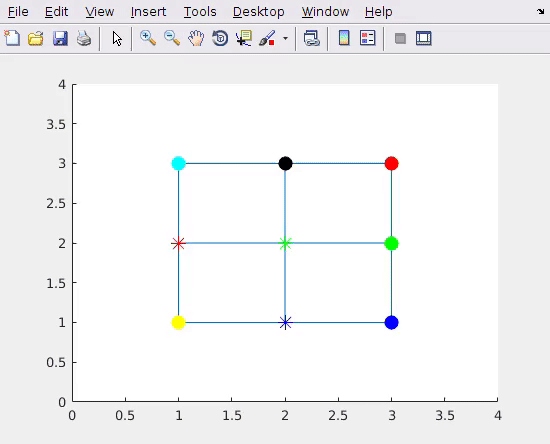

% this demo is based on nxn grid graph as the paper shows
% robots are on the grid and they can move just 4 basic direction.
% this demo runs just for any number of robot.

ngrid=3;
nrobot=9;

% create bidirectional grid as the same example in the paper in fig1
[Graph Loc Edge]=GridGraph(ngrid);

% plot the created grid-graph
figure; plot(Loc(:,1),Loc(:,2),'bo');
axis([0 ngrid+1 0 ngrid+1]);
hold on;
for i=1:2:size(Edge,1)
    x1=Loc(Edge(i,1),1);
    x2=Loc(Edge(i,2),1);
    y1=Loc(Edge(i,1),2);
    y2=Loc(Edge(i,2),2);
    line([x1;x2],[y1;y2]);
end

% set the maximum time step
ts=7;

% r1 2nd cell, r2 4th cell and r3 6th cell as start position
%sp=[2 4 6 1 ];
sp=[9 5 6 8 3 1 2 4 7];
% r1 8nd cell, r2 6th cell and r3 4th cell as end position
%ep=[8 6 4 9 ] + ngrid*ngrid*(ts-1);
ep=[7 8 9 4 5 6 1 2 3] + ngrid*ngrid*(ts-1);

% create time based graph which has ts times more node in figure 5 in paper
[tG,tedge,tloc]= createtimegraph(Graph,Edge,Loc,ts);

% solve the problem with a*, it is not the same with paper since they used
% ILP solver.
[route] = astar3(tG,tloc,sp,ep,ts);

% show the reults on the screen
clr={'r','g','k','b','cy','y','r','g','b'};
shp={'ro','go','ko','bo','cyo','yo','r*','g*','b*'};
sz=[0.8,1.6,2,2.2,2.6,3, 3, 3,3];
i=1;
figure; hold on;
for j=1:nrobot
    plot(tloc(route(i,j),1),tloc(route(i,j),2),[clr{j} 'o'],'MarkerFaceColor',clr{j},'MarkerSize',10);
    pl(j,:)=[tloc(route(i,j),1) tloc(route(i,j),2)];
end
axis([0 ngrid+1 0 ngrid+1]);
for i=1:2:size(Edge,1)
    x1=Loc(Edge(i,1),1);
    x2=Loc(Edge(i,2),1);
    y1=Loc(Edge(i,1),2);
    y2=Loc(Edge(i,2),2);
    line([x1;x2],[y1;y2]);
end
hold off;

for i=2:size(route,1)
    for j=1:nrobot
        cl(j,:)=[tloc(route(i,j),1) tloc(route(i,j),2)];
    end
    
    for iter=0:30
        clf
        for i=1:2:size(Edge,1)
            x1=Loc(Edge(i,1),1);
            x2=Loc(Edge(i,2),1);
            y1=Loc(Edge(i,1),2);
            y2=Loc(Edge(i,2),2);
            line([x1;x2],[y1;y2]);
        end
        axis([0 ngrid+1 0 ngrid+1]);
        hold on;
        for j=1:nrobot
            plot(pl(j,1)+iter*(cl(j,1)-pl(j,1))/30,pl(j,2)+iter*(cl(j,2)-pl(j,2))/30,shp{j},'MarkerFaceColor',clr{j},'MarkerSize',10);
        end
        pause(0.1);
        hold off;
    end
    
    pl=cl;
end